# Matrix Methods for Linear Systems

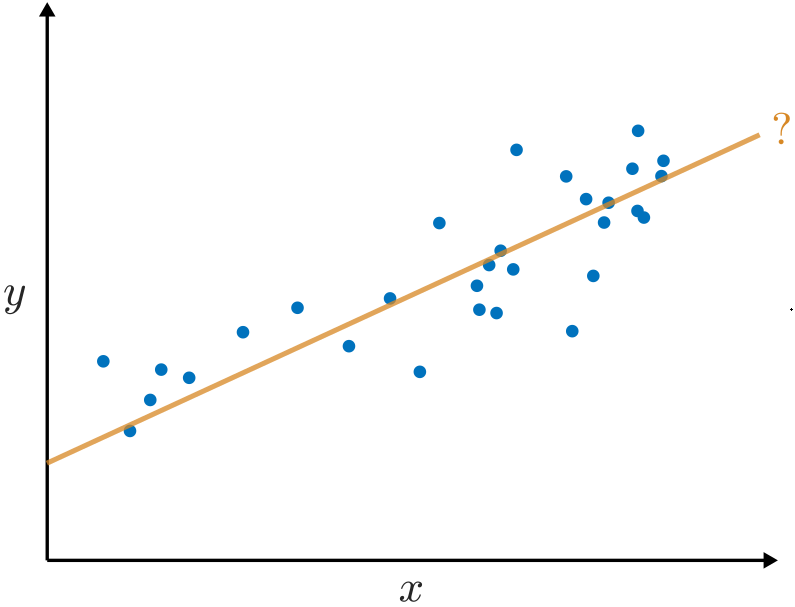                           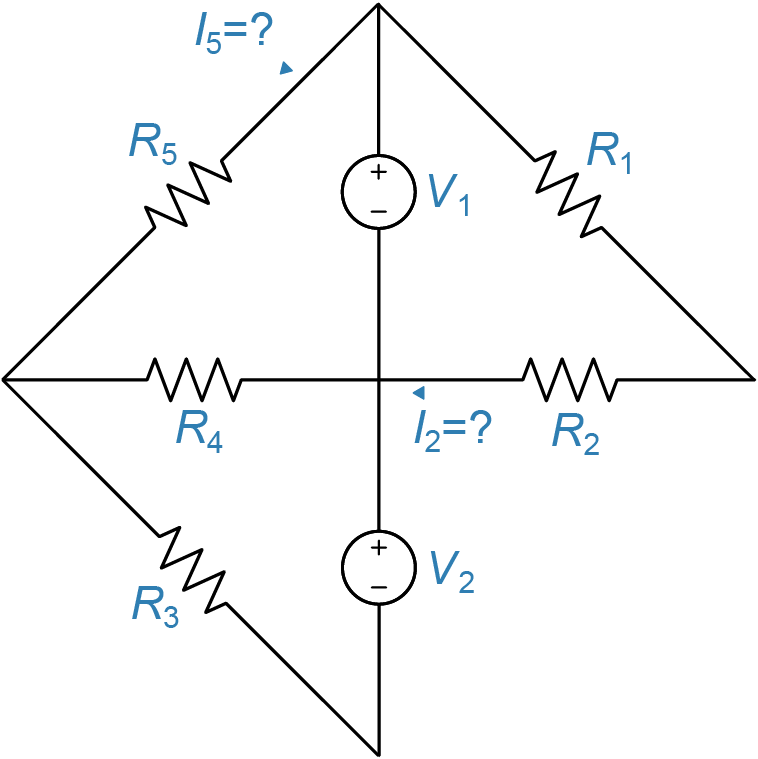

*Left panel: linear regression - what straight line best captures the data?*

*Right panel: a linear circuit composed of resistors and DC power sources. How much current flows through each branch?*

Linear regression is one of the most broadly used mathematical techniques. It is ubiquitous in traditional fields, like physics and biology, and modern disciplines, like machine learning. You've probably used linear regression yourself. But do you know how it is computed? 

It's easy to determine the current flowing through a branch of a small linear circuit with few calculations. However, in complex linear circuits, the current flows through many connected paths, complicating the problem. So how can you compute the current flowing through each branch without pages of tedious algebra?

The answers to both questions lie in the matrix methods of linear algebra. In this live script, you will learn how to represent, analyze, and solve linear systems in matrix form – both by hand and using MATLAB functions.

 Before you get started:

- Select the `VIEW` tab and switch to `Hide Code`.

## Systems of linear equations

**Definition**. A *linear equation* only contains terms that are either multiples of variables (e.g. $1.2x$) or constants. That is, it can be expressed in the form:

     
$$a_1x_1 + a_2x_2 + a_3x_3 +  \ldots = b$$


where $a_i$ and $b$ are constants and each $x_i$ is a variable.

**Definition**. A *system of linear equations* (also called a *linear system*) is a set of linear equations considered together.

- Linear systems can have a unique solution, an infinite set of solutions, or no solution. 

- In this live script, only systems with equal numbers of variables and equations are examined. *Overdetermined* (more equations than unknowns) and *underdetermined* (fewer equations than unknowns) systems are not considered.

- A 3-dimensional linear system can be visualized as a set of three planes. The intersection of all three planes represents the solution set.

** Example**. Consider the linear system

syms x y z a b c d
A = sym([0 1 1; 0 1 -2; a b c]);
bvec = sym([-1; 2; d]);
xvec = [x; y; z];
LinearSystem = A*xvec == bvec
 

Depending on the values of the constants $a$, $b$, $c$, and $d$, this system may have a unique solution, no solutions, or infinite solutions.

a =1; % Default: 1
b =-1; % Default: -1
c =-1; % Default: -1
d =-1; % Default: -1
 
A(3,:) = [a b c];
bvec(3) = d;
lims = [-6 6];
Plot3DSystem(A,bvec,lims); % This function plots the planes

  **Try**

- Set `a = -1`, `b = 0`, `c = 3`, and `d = 1 `and plot the system. 

- Hover over the plot to show the toolstrip and use the rotation tool   to find a good angle to view the solution. 

- Use the data tip tool   to estimate the numeric value of the solution. Record your estimated solution in the space provided below. You will validate it against the analytic solution in the next exercise.

MySltn = [""]

- Set `a = 0`, `b = -1`, `c = -3`, and `d = -2` and plot the system. What is the solution?

- Set `a = 0`, `b = -1`, `c = -3`, and `d = 3`. What is the solution?

** Exercise**. Use elimination or substitution to solve the linear system

    
$$\begin{array}{rl}
y+z&=-1\\
y-2\,z&=2\\
-x+3z&=1
\end{array}\
$$


ShowSolution = false;
if(ShowSolution)
    A = [0 1 1; 0 1 -2; -1 0 3];
    b = [-1; 2; 1];
    xvec = A\b;
    x = xvec(1)
    y = xvec(2)
    z = xvec(3)
end

 **Reflect. **Above, you graphically estimated the solution to be

if(exist("MySltn","var"))
    MySltn
else
    MySltn = ""
end

Were you close?

### **Writing a linear system in matrix form**

**Why write a linear system in matrix form?**

Matrix representations offer several advantages (especially for large systems of equations):

- Matrices offer a compact representation of a linear system

- Matrices are useful for representing solution algorithms 

- The solvability of a linear system can be ascertained through matrix properties

- Matrices are well suited for writing computational code

- Decompositions of matrices can offer meaningful insight into the dynamics of large systems

**Matrix form of a linear system**

You can write a system of $n$ linear equations with $n$ unknowns in matrix form as:

    
$$\mathbf{Ax} = \mathbf{b}$$


In this notation, $\mathbf{x}$ is a column vector of variables, $\mathbf{b}$ a constant column vector, and $\mathbf{A}$ an $n \times n$ coefficient matrix.

- Each row of $\mathbf{A}$ gives the coefficients for an equation.

- Each row of  $\mathbf{b}$ gives the constant right-hand side of an equation.

** Example**. Consider the linear system

    
$$\begin{array}{rl}
-x+3z&=1\\
y+z&=-1\\
y-2\,z&=2
\end{array}\
$$


(a) Write the linear system in matrix form using the solution variable

    
$$\mathbf{x} = \left( \matrix{x \cr y \cr z} \right)$$


(b) Verify that the matrix form is equivalent to the algebraic form by computing $\mathbf{Ax}$.

**Solution. (a)**

    1. The first row of $\mathbf{A}$ gives the coefficients of $x$, $y$, and $z$ in the first equation:

        $\mathbf{A} = \left(\begin{array}{ccc}
-1 & 0 & 3\\
&  &  \\
 &  & 
\end{array}\right)$.

    The second coefficient is 0 because it is the coefficient of the $y$ term in the first equation: $-x + \mathbf{0}y+3z =1

$.

    2. The remaining two rows are constructed similarly.

        
$$\mathbf{A} = \left(\begin{array}{ccc}
-1 & 0  &  3\\
0 & 1 & 1\\
0 & 1 & -2  
\end{array}\right)$$


    3. The constant column vector $\mathbf{b}$ is constructed the same way, with each constant representing the right-hand side of the corresponding equation.

        
$$\mathbf{b} = \left( \matrix{1 \cr -1 \cr  2} \right)$$


    4. With these definitions, $\mathbf{Ax} = \mathbf{b}$ is equivalent to:

        
$$ \left(\begin{array}{ccc}
-1 & 0  &  3\\
0 & 1 & 1\\
0 & 1 & -2  \\
\end{array}\right)\left( \matrix{x \cr y \cr z} \right)
=
 \left( \matrix{1 \cr -1 \cr 2} \right)$$


**(b)**

    If you multiply the left-hand side out, you will find

        
$$ \left(\begin{array}{ccc}
-x + 0y + 3z\\
0x  + 1y + 1z \\
0x  + 1y - 2z \\
\end{array} \right)
=
 \left( \matrix{1 \cr -1 \cr 2 } \right)$$


    equating each row of the two vectors implies:

        
$$\begin{array}{rl}
-x+3z&=1\\
y+z&=-1\\
y-2\,z&=2
\end{array}\
$$


    which is the original system.

** Exercise**. Consider the linear system:

    
$$\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}$$
  

(a) What are the coefficient matrix $\mathbf{A}$ and constant vector $\mathbf{b}$ of the system written in matrix form $\mathbf{Ax} = \mathbf{b}$?

ShowSolution = false;
if(ShowSolution)
    syms a b d
    A = sym([1 1 1; 1 1 -1; -1 1 1]) 
    b = sym([2; -2; 2])
end

(b) Compute the matrix-vector product $\mathbf{Ax}$ and write out the system $\mathbf{Ax} = \mathbf{b}$. Does the result match the original linear system?

** Exercise**. In this exercise you will show that a general matrix system $\mathbf{Ax} = \mathbf{b}$ is equivalent to a set of algebraic equations. Consider the general system of equations $\mathbf{Ax} = \mathbf{b}$ described by a coefficient matrix $\mathbf{A}$, solution vector $\mathbf{x}$, and constant column vector $\mathbf{b}$:

n =3;
A = sym("a",[n n]);
x = sym("x",[n 1]);
b = sym("b",[n 1]);
DisplayFormula("A*x = b")
 

1. Use MATLAB commands to compute the product $\mathbf{A}\mathbf{x}$ in the space below. `A`, `x`, and `b` are defined in the MATLAB Workspace.

Ax = [ ]

2. Set $\mathbf{Ax}$ equal to $\mathbf{b}$ using the Symbolic Math Toolbox in the space below.

  **Pro-tip. **For symbolic equality, use a double equal ([`==`](https://www.mathworks.com/help/symbolic/eq.html)`)`. This is necessary as a single equal sign (`=)` represents assignment to a variable in MATLAB.

eqs = [ ]

- Adjust `n` to view systems of different sizes.

## Solving linear systems i**n matrix form**

One method for solving the linear system in matrix form by hand is to use row reduction. Row reduction uses the same principles as elimination. Consider the system $\mathbf{Ax} = \mathbf{b}$:

n =3;
 
A = sym("a",[n n]);
x = sym("x",[n 1]);
b = sym("b",[n 1]);
c = sym("c",[n 1]);
DisplayFormula("A*x = b")

To solve this system by row reduction:

1. Write the system as an augmented matrix $(\mathbf{A} \ \mathbf{b} )$:

if(false)
    Ab = [A b]
end

2. Solve for the row-reduced form. If the system has a unique solution, the reduced form is:

if(false)
    RowReducedForm = [eye(n,n), c]
end

To solve for this form, you can use the same operations you use in elimination:

- Multiply any row by a constant

- Add a row to another row (multiplying by a constant before adding, if needed)

- Swap any row with another row

These are often termed *elementary row operations*. In this form, the solution to the system is the last column of $c_i$'s. Note that if there is not a unique solution, the reduced form will be different.

 **Reflect.**

- Write the row-reduced form of the system shown above as a matrix system. Then, compute the matrix product. Show that the solution is the last column of $c_i$'s.

- Relate each elementary row operation to the corresponding operation used in elimination.

- Adjust the size of the system, $n$. Does the row-reduced form change?

** Example**. Solve the linear system

    
$$\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}$$
 

using elementary row operations. 

**Solution.** The corresponding algebraic notation is shown for reference. The bold typeface is used to indicate that an operation has been performed.

                                                                          Matrix representation               Algebraic notation

                                                                           
$$\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
2
\end{array}\right)$$
                 
$$\left\{\begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
-x + y + z = 2
\end{array}\right.$$


1. Add row 1 to **row 3** **→**                                    $\left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
\mathbf 0& \mathbf 2 & \mathbf 2
\end{array}\right|
\left.\begin{array}{c}
2\\
-2\\
\mathbf 4
\end{array}\right)$                   $\left\{ \begin{array}{r}
x + y + z = 2
\\ 
x + y - z = -2
\\
\mathbf{2y + 2z = 4}
\end{array}$

2. Add  -1×row 1 to **row 2 →**                              $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & 0 & \mathbf{-2}\\
0 & 2 & 2
\end{array}\right|
\left.\begin{array}{c}
2\\
\mathbf{-4}\\
4
\end{array}\right)$                  $\left\{ \begin{array}{r}
x + y + z = 2
\\ 
\mathbf{- 2z = -4}
\\
2y + 2z = 4
\end{array}$

3. Swap **row 2 and 3** **→**                                     $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & \mathbf 2 & \mathbf 2\\
0 & 0 & \mathbf {-2}
\end{array}\right|\ 
\left.\begin{array}{c}
2\\
\mathbf{4} \\
\mathbf {-4}
\end{array}\right)$                $\left\{ \begin{array}{r}
x + y + z = 2
\\
\mathbf{2y + 2z = 4}
\\ 
\mathbf{- 2z = -4}
\end{array}$

4. Divide **row 2** by 2 and divide **row 3** by -2 **→**  $\left(\begin{array}{ccc}
1 & 1 & 1\\
0 & \mathbf  1 & \mathbf 1\\
0 & 0 & \mathbf{1}
\end{array}\right| \ 
\left.\begin{array}{c}
2\\
\mathbf {2}\\
\mathbf {2}
\end{array}\right)$                     $\left\{ \begin{array}{r}
x + y + z = 2
\\
\mathbf{y + z =  2}
\\ 
\mathbf{z = 2}
\end{array}$

5. Subtract row 2 from **row 1** **→**                         $\left(\begin{array}{ccc}
\mathbf{1} & \mathbf{0} & \mathbf{0}\\
0 & 1 & 1\\
0 & 0 & 1
\end{array}\right| \ 
\left.\begin{array}{c}
\mathbf{0} \\
2 \\
2
\end{array}\right)$                     $\left\{ \begin{array}{r}
\mathbf{x = 0}
\\
y + z = 2
\\ 
z = 2
\end{array}$

6. Subtract row 3 from **row 2** **→**                        $\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right| \ 
\left.\begin{array}{c}
0 \\
0 \\
2
\end{array}\right)$                     $\left\{ \begin{array}{r}
x = 0
\\
\mathbf{y  = 0}
\\ 
z = 2
\end{array}$

** Exercise**. Convert the solved matrix form (shown below) back into algebraic notation.

                
$$\left(\begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right| \ 
\left.\begin{array}{c}
0 \\
0 \\
2
\end{array}\right)$$


if(false)
    DisplayFormula(["'x' = 0";"'y' = 0";"'z' = 2"])
end

**Definition**. The solution form (obtained in step 6) is known as **reduced row echelon form** and is characterized by the following properties:

- The leading entry in each nonzero row is to the right of the leading entry of the preceding row.

- Each leading entry of a nonzero row is 1 and is called a **pivot**.

- Rows of all zeros are below nonzero rows.

- In any pivot column, every entry besides the pivot is zero.

In cases where there is a unique solution, the reduced row echelon form is an identity matrix.

** Exercise**. In this exercise, you will solve for the solutions of a linear system using row reduction.

(a) Write the system of equations

    
$$\begin{array}{rl}
2x + y + z &= \ \ 2
\\ 
4x + 2y + z &= -2
\\
4x + 2y + 5z &= 10 \ \ 
\end{array}$$


in matrix form.

(b) The linear system is plotted below. What solutions do you expect for the system? Will the reduced row echelon form be an identity matrix?

 
lims = [-6 6];
A = sym([2 1 4; 4 2 4; 2 1 5]);
bvec = sym([2; -2; 10]);
eqs = Plot3DSystem(A,bvec,lims); % This function plots the planes

(c) Solve for the reduced row echelon form of the system.

ShowSolution = false;
if(ShowSolution)
    ReducedRowEchelonForm = sym(rref([A,bvec]))
end

(d) Rewrite the reduced row echelon form as a system of equations in standard algebraic notation.

(e) What is the solution?

## Square matrix inverses

A *square matrix* has an equal number of rows and columns. Such matrices are suitable for representing systems with equal numbers of equations and unknowns. The **inverse** of a $n \times n$ matrix $\mathbf{A}$ (if it exists) is denoted $\mathbf{A}^{-1}$ and satisfies:

    
$$\mathbf{A}^{-1} \mathbf{A} = \mathbf{I}$$


where $\mathbf{I}$ is the $n \times n$ identity matrix. Note that not every square matrix has an inverse.

### **Solving linear systems using matrix inverses**

The solution of a linear system $\mathbf{Ax} = \mathbf{b}$ (if it exists) can be computed by row reduction operations. However, if you want to compute the solution for more than one $\mathbf{b}$, it is convenient to write the solution for an arbitrary $\textbf{b}$, and then evaluate the solution for a particular $\mathbf{b}$ as needed. The matrix inverse is suitable for this purpose.

Suppose that $\mathbf{A}$ is an invertible $n \times n$ matrix and you want to solve $\mathbf{Ax} = \mathbf{b}$ for an arbitrary constant vector $\mathbf{b}$:

              
$$\mathbf{Ax} = \mathbf{b}$$


        $\mathbf A^{-1} \mathbf{Ax} = \mathbf{A}^{-1} \mathbf{b}$             1. Left-multiply both sides of the equation by $\mathbf{A}^{-1}$.

               $\mathbf{Ix} = \mathbf{A}^{-1} \mathbf{b}$             2. Use the definition of the matrix inverse: $\mathbf{A}^{-1} \mathbf{A} = \mathbf{I}$.

                $\mathbf{x} = \mathbf{A}^{-1} \mathbf{b}$             3. The identity matrix definition yields $\mathbf{Ix} = \mathbf{x}$.

 This implies that you can compute the solution of the linear system as $\mathbf{x} = \mathbf{A}^{-1} \mathbf{b}$ for any constant right-hand side vector, $\mathbf{b}$. The only computation that will be required is the matrix product: $\mathbf{A}^{-1} \mathbf{b}$.

** Exercise**. Consider the matrices $\mathbf{A}$, $\mathbf{C}$, and $\mathbf{D}$:

 
A = sym([4 -1 0.5; 0.5 0.1 -0.5; 1 4 -0.5])
C = inv(A + [-2 0 0; 0 0 0; 0 0 0])
D = inv(A)

These matrices are defined in the MATLAB workspace.

(a) Use MATLAB commands in the spaces below to determine if $\mathbf{C}$ or $\mathbf{D}$ is the inverse of $\mathbf{A}$.

(b) The constant column vector $\mathbf{b}$ has been defined below. Use $\mathbf{C}$or $\mathbf{D}$ to compute the solution to $\mathbf{Ax} = \mathbf{b}$ in the space provided.

b = sym([-2; 1; -3])
x = [ ] 
IsEqualCheck(x,A\b);

(c) Verify that $\mathbf{x}$ solves the system $\mathbf{Ax} = \mathbf{b}$ by computing the matrix product $\mathbf{Ax}$ in the space provided and verify that the result is equal to $\mathbf{b}$.

### **Computing the matrix inverse by row reduction**

You can compute the inverse of a matrix $\mathbf{A}$ using row reduction operations. To do so:

1. Write the matrix together with an identity matrix as an augmented matrix: $(\mathbf{A} \ \mathbf{I})$. For example, for a 3x3 matrix this would be:

    
$$\left(\begin{array}{ccc}
a_{11} & a_{12} & a_{13}\\
a_{21} & a_{22} & a_{23}\\
a_{31} & a_{32} & a_{33}\\
\end{array}
\  \ \begin{array}{ccc}
1 & 0 & 0 \\
0 & 1 & 0 \\
0 & 0 & 1 
\end{array}\right)$$


2. Use row operations to convert $\mathbf A$ into the identity matrix. The operations are encoded in the right-side matrix, producing $\mathbf A^{-1}$.

    
$$\left(\begin{array}{ccc}
1 & 0 & 0 \\
0 & 1 & 0 \\
0 & 0 & 1 
\end{array}
\  \ \begin{array}{ccc}
 &  &  \\
 & \mathbf{A}^{-1} &  \\
 &  & 
\end{array}\right)$$


Note that if the inverse does not exist, it will not be possible to achieve this form. This is discussed in greater detail below.

** Example**. Solve for the inverse of $\mathbf A$ using row operations.

**Solution. **Move the slider forward to see the next step of the solution.

kstep = 1;

    
$$\mathbf A = 
\left(\begin{array}{ccc}
0.5 &  2 & 1\\
1 & 2 & -1\\
-1 & 0 & -4
\end{array}\right)
$$


InvDialogue(kstep);

** Exercise**. Verify by hand that $\mathbf{A}^{-1}$ computed in the example above is the inverse of $\mathbf A$ (verify that $\mathbf A^{-1} \mathbf A$ equals $\mathbf I$).

            $\mathbf A = 
\left(\begin{array}{ccc}
0.5 &  2 & 1\\
1 & 2 & -1\\
-1 & 0 & -4
\end{array}\right)
$,    $\mathrm{\mathbf A^{-1} =\ }\mathrm{}\left(\begin{array}{ccc}
-1 & 1 & -\frac{1}{2}\\
\frac{5}{8} & -\frac{1}{8} & \frac{3}{16}\\
\frac{1}{4} & -\frac{1}{4} & -\frac{1}{8}
\end{array}\right)$

### **Formulas for inverses of square matrices**

The inverse of a 2x2 matrix 

        $\mathbf A = \left(\begin{array}{cc}
a & b\\
c & d
\end{array}\right)$  is  $\mathbf A^{-1} = \frac{1}{ad - bc} \left(\begin{array}{cc}
d & -b\\
-c &a
\end{array}\right)$.

The inverse of a 3x3 matrix 

        $\mathbf A =
\left(\begin{array}{ccc}
a & b & c\\
d & e & f\\
g & h & i
\end{array}\right)$   is   $\mathbf A^{-1} =
\frac{1}{a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g}
\left(\begin{array}{ccc}
e\,i-f\,h & -b\,i+c\,h& b\,f-c\,e\\
-d\,i+f\,g& a\,i-c\,g & -a\,f+c\,d\\
d\,h-e\,g & -a\,h+b\,g & a\,e-b\,d
\end{array}\right)$.

For larger matrices, the formulas become quite complicated.

Show4x4 = false;
if(Show4x4)
    A = sym("a",[4,4])
    inv(A)
    disp("If this makes you feel dizzy, you can uncheck the box.")
end

  **Try **

- Use row-reduction to derive the general inverse of the 2x2 matrix $\mathbf A = \left(\begin{array}{cc}
a & b\\
c & d
\end{array}\right)$ by hand.

- Verify the formula for the 2x2 matrix inverse by computing the matrix product $\mathbf A^{-1} \mathbf A$ by hand.

 **Reflect**

- For many square matrices, the inverse does not exist. The existence of the general formula makes this fact a little surprising. Review the formulas for the inverses of the 2x2 and 3x3 matrices shown above. What condition would lead to an undefined inverse?

## **Invertibility of square matrices**

**Definition**. A $n\times n$ matrix is said to be **invertible** if its inverse exists.

Examining the formula for the matrix inverse can offer insight into the invertibility of a matrix. Consider the 2x2 matrix inverse:

    
$$\mathbf A^{-1} = \frac{1}{ad - bc} \left(\begin{array}{cc}
d & -b\\
-c &a
\end{array}\right)$$


If the denominator of the coefficient term is zero, i.e., $ad - bc = 0$, the matrix inverse will not be defined (terms in the matrix will be either $\frac{1}{0}$ or $\frac{0}{0}$).  

Similarly, in the $3 \times 3$ case

    $\mathbf A^{-1} =
\frac{1}{a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g}
\left(\begin{array}{ccc}
e\,i-f\,h & -b\,i+c\,h& b\,f-c\,e\\
-d\,i+f\,g& a\,i-c\,g & -a\,f+c\,d\\
d\,h-e\,g & -a\,h+b\,g & a\,e-b\,d
\end{array}\right)$.

the matrix inverse will be undefined if $a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g = 0$. 

 **Reflect**

- Does a similar condition exist for the 4x4 matrix inverse?

Show4x4 = false;
if(Show4x4)
    A = sym("a",[4 4])
    inv(A)
    disp("If this makes you feel dizzy, you can uncheck the box.")
end

### Matrix determinant

The determinant is a scalar value that characterizes the invertibility of a square ($n \times n$) matrix. 

- The determinant is not defined for non-square matrices. 

- Vertical lines $| \cdot |$ denote the determinant of a matrix. 

**Determinant of a 2x2 matrix**

The determinant of a 2x2 matrix is

    $|\mathbf{A}| = \left| \matrix{a & b \cr c & d } \right| = ad - bc$.

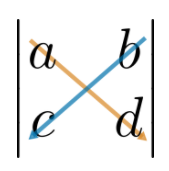

*You can think of the determinant of a 2x2 matrix as subtracting the product of the off-diagonal elements from the product of the diagonal elements.*

The determinants of larger matrices can be computed algorithmically using determinants of submatrices. This process is known as the Laplace expansion. 

**Determinant of a 3x3 matrix**

You can use the Laplace expansion to compute the determinant of a 3x3 matrix using 2x2 submatrices:

    
$$|\mathbf{A}|= \left| \matrix{a & b & c \cr d & e & f \cr g & h & i } \right| = a \left| \matrix{ e & f \cr h & i } \right| - b \left| \matrix{ d & f \cr g & i } \right|  +c \left| \matrix{ d & e \cr g & h } \right|$$


You can compute the determinants of the 2x2 submatrices using the formula defined above.

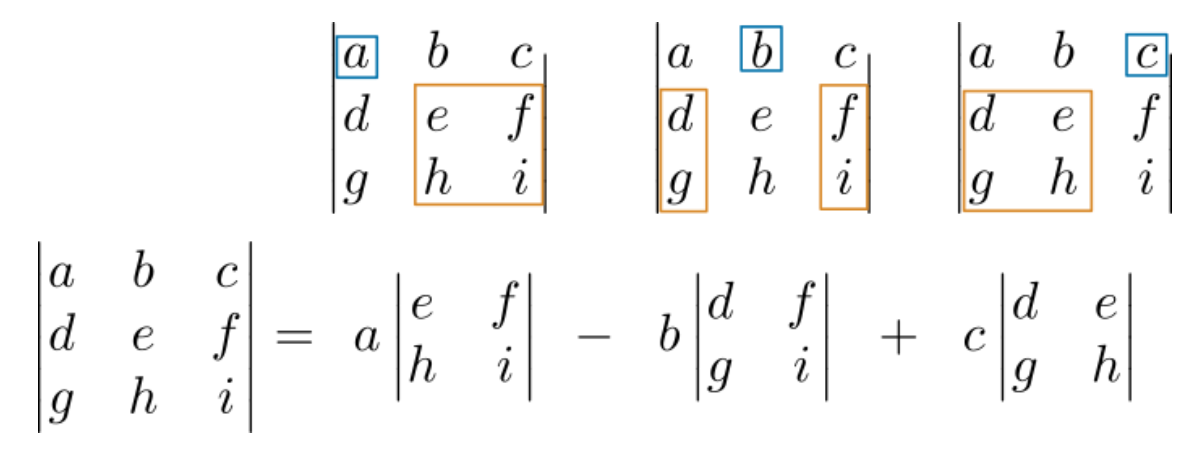

*Schematic of the Laplace expansion for a 3x3 matrix. Visualize selecting one element from the first row and then selecting the submatrix from the other rows and columns. Also watch out for the sign changes in the formula.*

Expanding the determinants of the submatrices yields the 3x3 determinant formula:

    
$$|\mathbf{A}|= a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g$$


You can similarly expand larger matrices to break them down in terms of smaller matrices. However, for such cases, numerical software is typically used.

 **Example**. Compute the determinant of $A$ using the Laplace expansion. You can adjust the size.

n = 3; 
 
A = sym(randi(9,n,n));
DisplayFormula(["'A = '", "A"])

ShowSolutiond = false;
if(ShowSolutiond)
    DetA = det(A)
end

**Determinant invertibility condition. **A square $n\times n$ matrix is invertible if and only if its **determinant **is nonzero.

- Note that the invertibility of a square matrix can be related to many other matrix properties outside the current discussion's scope.

**Understanding the determinant invertibility condition**

Consider the 2x2 determinant: $ad - bc$. This is the same expression as that found in the denominator of the matrix inverse. This implies that, for the inverse to be defined, $| \mathbf A| = ad - bc$ must be nonzero.  You can also write the formula for the inverse as:

    $\mathbf A^{-1} = \frac{1}{|\mathbf A|} \left(\begin{array}{cc}
d & -b\\
-c &a
\end{array}\right)$. 

The concept extends to higher-dimensional matrices. In the 3x3 case, the determinant is $|\mathbf A| = a\,e\,i-a\,f\,h-b\,d\,i+b\,f\,g+c\,d\,h-c\,e\,g$. So, the inverse formula is

    $\mathbf A^{-1} =
\frac{1}{|\mathbf A|}
\left(\begin{array}{ccc}
e\,i-f\,h & -b\,i+c\,h& b\,f-c\,e\\
-d\,i+f\,g& a\,i-c\,g & -a\,f+c\,d\\
d\,h-e\,g & -a\,h+b\,g & a\,e-b\,d
\end{array}\right)$,

which is well defined if and only if $|\mathbf A| \neq 0$.

** Exercise**. 

(a) Determine if the matrices are invertible.


$$\mathbf A = 
 \left(\begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
8 & 9 & 10
\end{array}\right)$$
        
$$\mathbf{B} = 
 \left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right)$$
          
$$\mathbf{C} = 
\left(\begin{array}{ccc}
1 & 0.5 & -1\\
0 & 2 & 1\\
-4 & 1 & 1
\end{array}\right)$$
        

ShowSolution = false;
As = [1 2 3; 4 5 6; 8 9 10];
Bs = [1 1 1; 1 0 0; 0 0 1];
Cs = [1 0.5 -1; 0 2 1; -4 1 1];
if(ShowSolution)
    disp("|A| = " + string(det(sym(As))) + " so the matrix is not invertible.")
    disp("|B| = " + string(det(sym(Bs))) + " so the matrix is invertible.")
    disp("|C| = " + string(det(sym(Cs))) + " so the matrix is invertible.")
end

(b) Compute the inverse of the invertible matrices using either

- the formula

- row reduction

(c) Define the matrices $\mathbf{A}$, $\mathbf{B}$, and $\mathbf{C}$ in MATLAB below. Recall that semicolons are used to separate rows, and spaces or commas are used to separate columns. For example: `[0 1; 2 3]`.

A = sym([ ])
B = sym([ ])
C = sym([ ])

  **Pro-tip**: You can also compute the inverse using MATLAB. You can compute the inverse of a matrix C in MATLAB using the syntax: `inv(C)`. Try computing the inverse of the invertible matrices below.

(d) Compute the inverse of each matrix below using `inv`. What solution is shown for non-invertible matrices?

Ainv = [ ]
Binv = [ ]
Cinv = [ ]
 

** Exercise**. In this exercise, you will use the matrix inverse to compute the solutions to a linear system $\mathbf{Ax} = \mathbf{b}$ with

    $\mathbf A = \left(\begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & -1\\
-1 & 1 & 1
\end{array}\right)$.

(a) Compute $\mathbf{A}^{-1}$ using either row reductions or the formula for 3x3 matrices.

ShowSolutionA = false;
A = sym([1 1 1; 1 1 -1; -1 1 1]);
if(ShowSolutionA)
    Ainv = inv(A) 
end

(b) Solve the system by computing the matrix product $\mathbf{A}^{-1} \mathbf{b}$ with

    $\mathbf{b} = \left( \matrix{ 1 \cr 0 \cr -1 } \right)$.

ShowSolutionB = false;
b = [1; 0; -1];
Ainv = inv(A);
if(ShowSolutionB)
    x=A\b
end

(c) Solve the system for $\mathbf{x}$ with

    $\mathbf{b} = \left( \matrix{ 2 \cr -5 \cr 10 } \right)$.

ShowSolutionC = false;
b = [2; -5; 10];
if(ShowSolutionC)
    x=A\b
end

### **Characterization of linear system solutions in terms of matrices**

An important feature of the matrix representation is that it allows you to quickly compute whether a system of equations has a unique solution. Consider a linear system with $n$ equations and $n$ unknowns. It can be represented in matrix form as

    
$$\mathbf{Ax} = \mathbf{b}$$


For this system, the following are equivalent (this is part of the **Invertible Matrix Theorem**):

- $\mathbf{A}$ is invertible

- $|\mathbf{A}|$ is nonzero

- The linear system has a unique solution for every $\mathbf{b}$ in $\mathbb{R}^n$.

If you want to check if a system has a unique solution, you can represent the system in matrix form, and then compute $|\mathbf{A}|$. If the determinant is nonzero, the system has a unique solution for any $\mathbf{b}$.

** Exercise**. Determine if the systems have a unique solution by (1) writing the system in matrix form and (2) computing the determinant of the coefficient matrix.

(a)  $\begin{array}{r}
2x +y = 2
\\ 
x - y  = 10
\end{array}$  

ShowSolutionA = false;
syms x y z
A = sym([2 1; 1 -1]);
b = sym([2; 10]);
xvec = [x; y];
if(ShowSolutionA)
    DisplayFormula([char(A),char(xvec),"' = '",char(b)]);
    disp("|A| = " + string(det(A)) + " which is nonzero. This implies that the system has a unique solution.")
end

(b) $\begin{array}{r}
2x +y + 4z = 2
\\ 
x - z = 10
\\ 
-3x + 2 y - z = 11
\end{array}$  

ShowSolutionB = false;
A = sym([2 1 4; 1 0 -1; -3 2 -1]);
b = sym([2; 10; 11]);
xvec = [x; y; z];
if(ShowSolutionB)
    DisplayFormula([char(A),char(xvec),"' = '",char(b)]);
    disp("|A| = " + string(det(A)) + " which is nonzero. This implies that the system has a unique solution.")
end

## **Working with linear systems in MATLAB**

Small systems of equations are not difficult to solve by hand using row reduction or inverses. But what happens if the system has tens, hundreds, or even thousands of variables? 

Adjust the slider to select the size of the system $\mathbf{Ax} = \mathbf{b}$:

n = 15;
A = randi(20,[n n])-10;
b = randi(20,[n 1])-10;
x = sym("x",[n 1]);
DisplayFormula([char(sym(A)),char(sym(x)),"' = '",char(sym(b))]);

Solving this system by hand isn't a viable option. You'll want to use numerical software to solve your system. In MATLAB, you can define a linear system $\mathbf{Ax} = \mathbf b$ in terms of matrices and vectors and solve the system using built-in functions. There are two approaches: numeric and symbolic. In this section, you will explore both approaches. In general, the same basic functions for working with matrices (such as `inv` and `det`) work for both symbolic and numeric matrices. In this section, the solution vector is expressed as:

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n} \right)$.

** Exercise**. In this exercise, you will analyze and solve a linear system using numeric matrices. Perform the tasks using MATLAB commands in the space provided.

   **Task 1. **Determine if the system $\mathbf{Ax} = \mathbf{b}$ defined above has a unique solution. The matrix $\mathbf{A}$ is stored in the variable `A `and the vector $\mathbf{b}$ is stored in `b`.

**Hint**: use the MATLAB determinant function: [`det`](https://www.mathworks.com/help/matlab/ref/det.html).

answer = 0;
IsEqualCheck(answer,det(A)~=0);
 

   **Task 2. **Compute the inverse of `A`.

InvA = [ ]
 
IsEqualCheck(inv(A),InvA);

**Hint**: [`inv`](https://www.mathworks.com/help/matlab/ref/inv.html).

   **Task 3. **Use the inverse InvA to compute the solution to $\mathbf{Ax} = \mathbf{b}$.

xSoln1 = [ ]
 
IsEqualCheck(xSoln1,inv(A)*b);

There are other (and often better) ways to solve a linear system in MATLAB than the inverse. The most common method is using the [backslash operator](https://www.mathworks.com/help/matlab/ref/mldivide.html) (`\`). Conceptually, this operator is equivalent to a "left divide". Thus, using this operator, the solution to a linear system 

`    Ax = b`

is found by "left-dividing" `b` by `A`. In quasi-mathematical terms:

`  A\Ax = A\b`

`     x = A\b`

   **Task 4.** Use the left divide operator to solve the linear system $\mathbf{Ax} = \mathbf{b}$.

xSoln2 = [ ];
 
xSoln2
IsEqualCheck(xSoln2,A\b);

   **Task 5.** Is the solution computed using the inverse the same as the solution computed using the backslash operator? To find out, try taking the differences of the two solutions: `xSoln1` and `xSoln2`.

 **Reflect**

- Is either solution exact?

- In general, numeric solutions computed with different algorithms will be different. What causes these differences?

- For small matrices, the method is typically not important. However, for large matrices, the inverse is not the preferred method as it can lead to large numerical errors.

** Exercise**. In this exercise, you will analyze and solve a linear system using symbolic variables. Perform the tasks using MATLAB commands in the space provided.

   **Task 1. **Several symbolic variables are defined below. Define a matrix $\mathbf{C}$ and a constant vector $\mathbf{d}$. Choose any values for $\mathbf{C}$ and $\mathbf{d}$ that satisfy:

- $\mathbf{C}$ is an $n \times n$ numeric matrix 

- $\mathbf{d}$ is an $n$-element numeric column vector

- both $\mathbf{C}$ and $\mathbf{d}$ have some symbolic elements and some numeric elements

You can decide how large to make the matrices (e.g., $n = 3$).

syms a b c r p q 
C = [ ]
d = [ ]
if(size(d,1)~=size(C,1))
    warning("d should have the same number of rows as C!")
end
if(size(C,2)~=size(C,1))
    warning("C should be square!")
end
if(size(d,2)>1)
    warning("d should be a column vector!")
end

   **Task 2. **The symbolic variable vector $\mathbf{x}$ is defined below. Use it to compute the algebraic form of the linear system $\mathbf{Cx} = \mathbf{d}$.

x = sym("x",[length(d),1])
LinearSystem = [ ]
try
    IsEqualCheck(LinearSystem,C*x==d);
catch ME
    warning("Check failed due to: " + ME.message)
end

  **Pro-tip. **For symbolic equality, use [`==`](https://www.mathworks.com/help/symbolic/eq.html). 

   **Task 3. **What condition on the constants will make the system $\mathbf{Cx} = \mathbf{d}$ have a unique solution? Type your condition in the space provided below using symbolic variables and operators.

condition = [ ]
try
    IsEqualCheck(simplify(condition), simplify(det(C)~=0));
catch ME
    warning("Check failed due to: " + ME.message)
end

**Hint**: [`det`](https://www.mathworks.com/help/matlab/ref/det.html) and the symbolic inequality operator: [~=](https://www.mathworks.com/help/symbolic/ne.html)`.`

   **Task 4. **Compute $\mathbf{C}^{-1}$.

Cinv = [ ];
 
Cinv
IsEqualCheck(Cinv,inv(C));

   **Task 5. **The inverse that you computed is stored in a variable `Cinv`. Use it to compute the solution $\mathbf{x}$ to the linear system $\mathbf{Cx} = \mathbf{d}$.

xSoln1 = [ ];
 
xSoln1
IsEqualCheck(xSoln1,Cinv*d);

   **Task 6. **Compute the solution to $\mathbf{Cx} = \mathbf{d}$ using the [backslash operator](https://www.mathworks.com/help/matlab/ref/mldivide.html) (\).

xSoln2 = [ ];
 
xSoln2
IsEqualCheck(xSoln2,C\d);

   **Task 7.** Is the solution computed using the inverse the same as the solution computed using the backslash operator? To find out, try taking the differences of the two solutions: `xSoln1` and `xSoln2`.

**Hint**: if the difference of the answers is nonzero, it is likely because the symbolic expression was not simplified. You can use the [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html) function to simplify the expression.

 **Reflect**

- Is either solution exact?

- In most cases, numeric solutions are used rather than symbolic ones. Why is this the case?

- In what situations would you be interested in a symbolic solution rather than a numeric one?

## Applications: Linear regression and linear circuits

To view the applications, open the live script [LinearSystemsApplications.mlx](matlab: open LinearSystemsApplications.mlx). Note that the live script must be in the [MATLAB Search Path](https://www.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html) for this link to work.

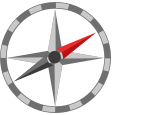**Further exploration**

- You can learn more about linear systems and solving them in MATLAB in the online course [Introduction to Linear Algebra with MATLAB](https://www.mathworks.com/learn/tutorials/introduction-to-linear-algebra-with-matlab.html).

- To learn more about symbolic math, check out the online training course [Introduction to Symbolic Math with MATLAB](https://www.mathworks.com/learn/tutorials/introduction-to-symbolic-math-with-matlab.html).

function eqs = Plot3DSystem(A,bvec,lims)
% This plots a 3D system of equations of the form Ax = b
    % Solve for z
    syms x y z
    xvec = [x; y; z];  
    eqs = A*xvec == bvec;
    f1 = solve(eqs(1),z);
    f2 = solve(eqs(2),z);
    f3 = solve(eqs(3),z);
    fm1 = matlabFunction(f1,"Vars",[x y]);
    fm2 = matlabFunction(f2,"Vars",[x y]);
    fm3 = matlabFunction(f3,"Vars",[x y]);
    % Create the plot
    c = lines(5);
    figure('position',[0 0 600 600])
    fsurf(fm1,lims,"facecolor",c(1,:),"facealpha",0.5,"edgecolor","none")
    hold on;
    fsurf(fm2,lims,"facecolor",c(2,:),"facealpha",0.5,"edgecolor","none")
    fsurf(fm3,lims,"facecolor",c(3,:),"facealpha",0.5,"edgecolor","none")    
    if(det(A)~=0)
        x = A\bvec;
        plot3(x(1),x(2),x(3),"go","MarkerFaceColor","G")
    end
    hold off
    axis equal;
    view (10,30); 
    axis tight
    legend("eq1","eq2","eq3")
    xlabel("x")
    ylabel("y")
    zlabel("z")
end

function InvDialogue(k)
% This generates a dialogue to walk through the row reduction of a
% particular matrix (defined below)
    AI = [];
    AIprev = AI;
    for i = 1:k
        switch i
            case 1
                text = "1. Write A and I together as a single augmented matrix";    
                AI = sym([0.5 2 1 1 0 0; 1 2 -1 0 1 0; -1 0 -4 0 0 1]);
            case 2
                text = "2. Add row 2 to row 3";
                AI(3,:) = AI(3,:) + AI(2,:);
            case 3
                text ="3. Add -2*row 1 to row 2";
                AI(2,:) = AI(2,:) + -2*AI(1,:);
            case 4
                text ="4. Multiply row 1 by 2";
                AI(1,:) = 2*AI(1,:) ;
            case 5
                text ="5. Add row 2 to row 3";
                AI(3,:) = AI(3,:) + AI(2,:);
            case 6
                text = "6. Divide row 2 by -2 and row 3 by -8";
                AI(2,:) = AI(2,:)/-2;
                AI(3,:) = AI(3,:)/-8;
            case 7
                text = "7. Subtract -1.5*row 3 from row 2";
                AI(2,:) = AI(2,:) - 1.5*AI(3,:);
            case 8
                text = "8. Subtract -4*row 2 and -2*row 3 from row 1";
                AI(1,:) = AI(1,:) - 4*AI(2,:) - 2*AI(3,:);
            case 9
                text = "The matrix inverse is contained in the last three columns.";
            otherwise
                AI = sym([0.5 2 1; 1 2 -1; -1 0 -4]);
                k = 0;
                text = "0. The matrix A:";
        end 
        if( i == k-1 )
            AIprev = AI; 
        end
    end
    
    AI = combine(AI);
    DisplayFormula("'" + text + " '")
    if(k == 9)
        AI46 = AI(:,4:6);
        DisplayFormula(["'A⁻¹ = '", "AI46"]);
    elseif (k == 1)
        DisplayFormula("AI");
    else      
        DisplayFormula(["AIprev" , "'→'" , "AI"])
    end
end

function correct = IsEqualCheck(UserSubmission, CorrectAnswer)
% This function checks if two results are equal and displays feedback
    correct = true;
    if( isequal(UserSubmission, CorrectAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

% Suppress unusued suggestions
%#ok<*IJCL> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*NBRAK> 
%#ok<*NODEF>
%#ok<*NASGU> 